# Intro to Image Segmentation

[⇦ Main Menu](matlab:open('../MainMenu.mlx'))

An overview and application of image segmentation techniques used in Computer Vision. 

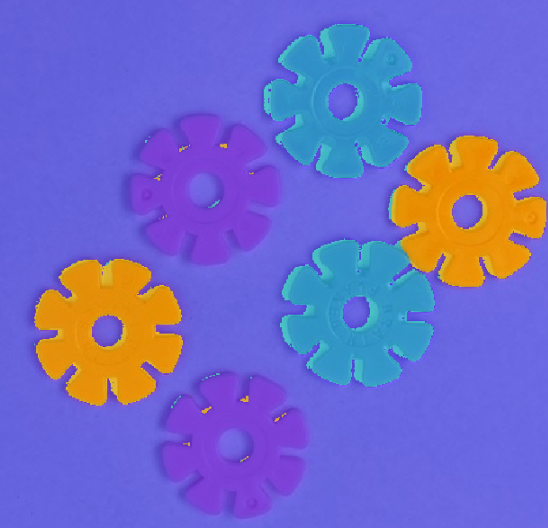

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Overview of Image Segmentation Techniques

In computer vision, image segmentation involves dividing an image into multiple segments or regions, each representing a distinct object or part of an object, based on pixel characteristics. This segmentation simplifies the image, making it easier to analyze. Segmentation aims to identify edges and regions in images to create areas that are significant for understanding the content, such as objects or boundaries. **Edges** are detected based on differences between adjacent pixels, whereas **regions** are detected based on similarities between pixels. Edges are often detected, and then regions are filled in from those. Edge and region detection occur in the *xy* space. With videos and motion, we include the *t* space and use **optical flow** techniques to segment images based on motion.

To start analyzing this data, it's essential to produce simplified representations that highlight important features while reducing detail. Key properties of images that help create these simplified representations include:

- **Edges**: Boundaries between different regions in an image.

- **Segmentation**: Dividing the image into meaningful segments.

- **Optical Flow**: The pattern of apparent motion of objects in a visual scene.

## Edge Detection

Edge detection is a fundamental technique in image processing and computer vision used to identify boundaries within an image. To detect edges, we examine changes in brightness from one pixel to the next. Significant changes in brightness indicate edges and outlines within the image. For example, moving from a very bright pixel to a very dark pixel represents a significant change in brightness, usually indicating an edge. Edges are the outlines or boundaries of objects in the image. Conversely, if the brightness changes only slightly, it indicates a smooth, continuous area with no edge. The result of edge detection is a binary image where the edges are highlighted. This processed image can then be used for further analysis, such as identifying shapes, detecting objects, or enhancing image quality.

**Possible Scenario: **Imagine a building maintenance team tasked with ensuring the structural integrity and aesthetic appearance of brick walls. One of their responsibilities is to monitor the condition of the mortar between the bricks and determine when repointing or replacing the mortar is necessary. Edge detection can be a valuable tool in this scenario. By capturing images of the brick walls, the team can use edge detection algorithms to identify the boundaries between the bricks and the caulk (mortar). This process involves analyzing the differences in pixel intensity to highlight the edges where the mortar meets the bricks.

  **Try**. Select an image to see the results of a standard edge detection algorithm.

option = "Beach.jpg";
if ~strcmp(option,"Select")
    ImGauss = imread(option); %#ok<*UNRCH> % Load image
    ImGaussG = im2gray(ImGauss); % Convert image to grayscale
    ImGaussG = edge(ImGaussG,"Sobel"); % Find edges in original image
    ImGaussG = im2double(ImGaussG);

    figure
    montage({ImGauss,ImGaussG},Size=[1,2])

    ax3 = gca;
    ax3.PositionConstraint = "outerposition";
    title("Original Image (Left) and Edge Detected Image (Right)")
    if strcmp(option,"PipeBlue.jpg")
        fprintf('<a href="https://commons.wikimedia.org/wiki/File:Plastic_courrugated_pipe.jpg#filelinks">Image of Plastic Corrugated Pipes</a>\n')
    end
else
    warning("Select a valid option.")
end

 **Reflect**. If you use the simplified image (edge-detected image) of the blue pipes, would you be able to take that image and count the pipes? 

### Noise Removal - Smoothing Images

Noise in an image can complicate edge detection by introducing random intensity variations that mimic edges. To mitigate this, we use image filters like the Gaussian filter, which smooths the image by averaging surrounding pixels. The standard deviation, sigma (σ), of the Gaussian function controls the smoothing level; a higher sigma value results in more noise suppression. This process enhances the accuracy of edge detection by making true edges clearer and reducing the impact of noise.

  **Try**. Remove the noise from the image to improve edge detection.

- *Select an image to display.*

- *Adjust the sigma value to remove noise from the image. *

optionB = "PipeBlue.jpg";
if ~strcmp(optionB,"Select")
    ImGauss2 = imread(optionB); % Load original image
    ImGaussG2 = im2gray(ImGauss2); % Convert image to grayscale
    ImGaussG2 = edge(ImGaussG2,"Sobel"); % Find edges in original image

    % Smooth the image with a Gaussian filter
    ISmoothed = imgaussfilt(ImGauss2,1);
    ISmoothedG = im2gray(ISmoothed); % Convert smoothed image to grayscale for edge processing
    ISmoothedG = edge(ISmoothedG,"Sobel"); % Find edges in smoothed image


    figure

    montage({ImGauss2,ImGaussG2},Size=[1,2])

    ax4 = gca;
    ax4.PositionConstraint = "outerposition";
    title("Original Image (Left) and Edge Detected Original Image (Right)")
    figure
    montage({ISmoothed,ISmoothedG},Size=[1,2])
    ax7 = gca;
    ax7.PositionConstraint = "outerposition";
    title("Smoothed Image (Left) and Edge Detected Smoothed Image (Right)")
    if strcmp(optionB,"PipeBlue.jpg")
        fprintf('<a href="https://commons.wikimedia.org/wiki/File:Plastic_courrugated_pipe.jpg#filelinks">Image of Plastic Corrugated Pipes</a>\n')
    elseif strcmp(optionB,"StackOfPipes.jpg")
        fprintf('<a href="https://commons.wikimedia.org/wiki/File:StackOfPipes2.jpg">Image of Stack of Pipes</a>\n')
    end
else
    warning("Select a valid option.")
end

### Use Canny Method to Detect Edges

The Canny method is widely used for edge detection due to its superior performance in accurately detecting edges while minimizing noise. It employs a multi-stage process: first, smoothing the image with a Gaussian filter, then calculating the gradient using the Sobel operator. The method continues with non-maximum suppression to thin out edges, Double thresholding to classify edges as strong, weak, or non-edges, and finally, edge tracking by hysteresis to connect weak edges to strong ones, ensuring continuous and precise edge detection.

  **Try**. Use the Canny Edge detector to detect edges.

- *Select an image to display.*

- *Select a sigma value for the Gaussian filter.*

    ImageC = "Brick.jpg";
    if ~strcmp(ImageC,"Select")
        ImageC = imread(ImageC);
        ImageCG = im2gray(ImageC); % Convert the loaded image to grayscale

        [~,threshOut] = edge(ImageCG);

        % Use the edge function to detect edges in the grayscale image
        BWImageCG = edge(ImageCG,"Canny",threshOut,1);
        BWImageCG = im2double(BWImageCG);

        figure
        montage({ImageC,BWImageCG},Size=[1,2])
        ax5 = gca;
        ax5.PositionConstraint = "outerposition";
        title({"Original Image (Left) and";"Canny Method Edge Detected Image (Right)"})

    else
        warning("Select a valid option.")
    end

 **Reflect**. What happens to the edge-detected image as you increase the sigma value for the Gaussian filter or increase blurring? Do you lose or gain new edges in your edge-detected image? 

## Region Segmentation

Region segmentation involves grouping pixels in an image into regions based on certain criteria, such as color, intensity, or texture. Pixels within the same region share similar properties. For example, in a color image, all pixels in a region might have similar colors. The goal is to partition the image into meaningful segments.

**Possible Scenario: **Let's say you've reported graffiti through your town's community app, and they promised to remove it within a week. To check if the graffiti has been removed, you could use region segmentation to compare before and after images of the wall. By segmenting the graffiti from the wall, you can easily identify changes and verify if the graffiti has been removed.

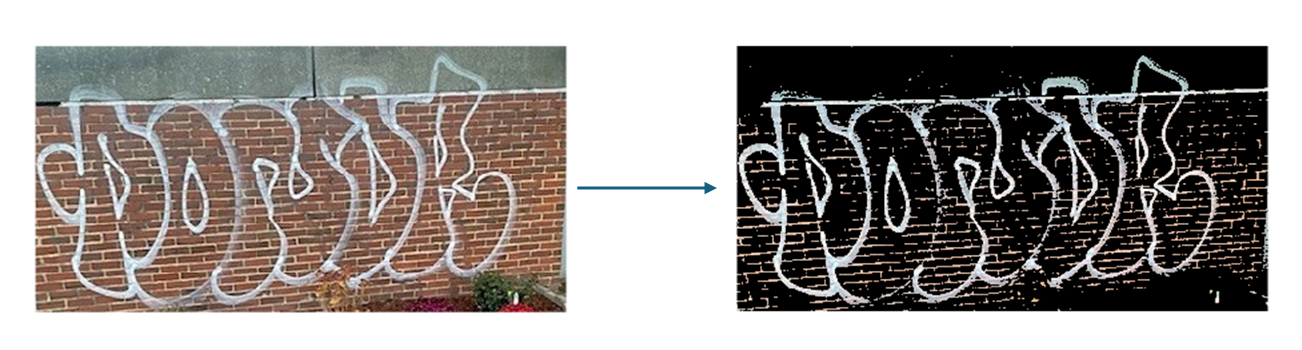

For an image of the ocean, edge detection is useful for identifying boundary lines between different areas. For example, it can highlight the boundaries between the sand and water or between the sky and clouds. However, edge detection alone may not be helpful in distinguishing areas of similarity within those regions.

Region segmentation can then be used to isolate different areas such as the sand, water, sky, and clouds. This technique helps in distinguishing these regions based on their pixel characteristics.

### Segmentation by Intensity

Each pixel in an image has an intensity value, which represents its brightness. In grayscale images, this value ranges from 0 (black) to 255 (white). Segmentation by intensity involves grouping pixels with similar intensity values into regions. This helps in identifying areas with similar brightness levels.

  **Try**. View a segmentation of the beach image based on pixel intensity or brightness. 

    option2 = "Beach.jpg"; 
    segImage = imread(option2);

    % Convert the loaded image to grayscale
    grayImage = im2gray(segImage);

    %Binarize grayscale image
    BWImg = imbinarize(grayImage);

    % Display the original and segmented images
    figure
    montage({segImage,BWImg},Size=[1,2])
    title("Original Image (Left) and Segmented Image (Right)");

 **Reflect**. What information is lost when you segment based on intensity alone?

### Segmentation by Color

Recall, in region detection, we are looking for similarities in pixels. We can categorize similarities based on intensities or colors. We can accomplish this color-based region identification efficiently using **k-means clustering**. **K-means clustering** is effective for segmenting color images by grouping similar pixels into clusters, simplifying the identification of different regions. It's computationally efficient and can be applied to various color spaces (e.g., RGB, HSV), making it versatile for tasks like object detection, image compression, and feature enhancement.

The L*a*b*** color space is preferred over RGB in image analysis because its perceptual uniformity aligns more closely with human vision, thus making color differences easier to detect and quantify. L*a*b*** separates luminance or lightness (L*) from color information a* and b*, allowing for independent manipulation of brightness and color.

To segment by color, we first convert the image to the L*a*b* space and then use k-means clustering to visualize the number of color-based clusters. Remember, each cluster represents similar pixels.

  **Try**. Use **k-means clustering** to color-segment images. You can even see if the graffiti was removed from the brick wall. 

- *Select an image.*

- *Vary the number of clusters to partition the image into individual colors.*

    ImageA = "Graffiti.jpg";
    k = 3;
     
    if ~strcmp(ImageA,"Select")
        ImageA = imread(ImageA);
        LA = KImClust(ImageA,k);
        montage({ImageA,labeloverlay(ImageA,LA)},Size=[1,2])
        title("Original Image(Left) and Labeled Color-Segmented Image (Right)")
    else
        warning("Select a valid option.")
    end

  **Try**. Visualize each cluster by selecting a target cluster below.

    % Choose a specific cluster to segment
     

    if exist("LA","var") ||~exist("k","var")
        TargetCluster = 3; % Change this value for different clusters
        NewSegIm = VizClust(ImageA,LA,TargetCluster);
        montage({labeloverlay(ImageA,LA);NewSegIm},Size=[1,2])
        ax2 = gca;
        ax2.PositionConstraint = "outerposition";
        title("Segmented Image (Left) and Selected Cluster # "+TargetCluster+" (Right)")
    else
        disp("Please apply k-means clustering to an image above. section above.")
    end

 **Reflect**. What happens when the values for k are too large? Or too small?

## Optical Flow 

**Optical flow **refers to the perceived motion of brightness patterns in an image, calculated by analyzing changes in pixel intensity over time. This apparent motion includes objects, surfaces, and edges within a visual scene, resulting from the relative movement between the observer and the scene. **Optical flow vectors** represent the direction and magnitude of pixel movement in an image sequence, mapping the apparent motion of objects, surfaces, and edges. This is crucial for applications like motion detection, object tracking, and video stabilization. 

We can create a **motion color intensity map** from an optical flow vector image to help us visually interpret the magnitude of motion in a scene more clearly. By mapping motion magnitude to specific colors—dark blue for stationary or slow-moving objects and light blue or green for faster-moving objects—we generate a color intensity map that represents motion visually. This approach is particularly valuable in applications like video surveillance, sports analysis, and autonomous driving, where understanding motion patterns is crucial for decision-making and analysis.

**Possible Scenario:** Consider scientists who are studying coastal erosion. They have a stationary camera that captures images of the same area at the same time every day. The scientists could use **edge detection** to distinguish the sea from the coastline in individual images by identifying the boundary lines between the sea and the land. They could also use **region segmentation** to compare and contrast the sizes of the regions representing the sea and the land, allowing them to quantify the areas and observe changes over time. To determine the rates of coastal erosion over time, the scientists will use **optical flow** to map the apparent motion of the sea. This technique analyzes the movement of pixels between consecutive frames in the video, helping to track how the coastline changes over time.

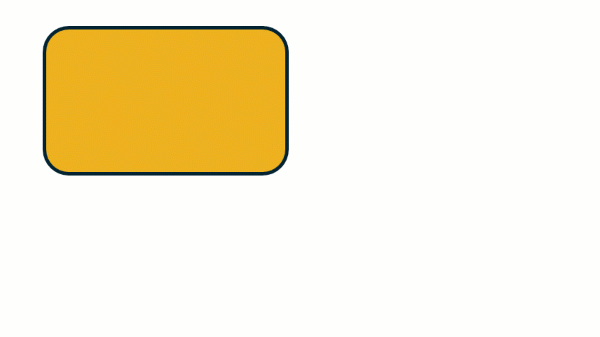

  **Try**. Analyze the movie above with **optical flow.**

- *Select the number of frames between the last image and the first image in the video you will compare. *

- *Visualize the optical flow vector fields below between two frames of the video and calculate the speed. *

- *View the motion intensity color map.*

    % Create an object to read the input video file.
    ChosenMovie = "VidOptFlow.mp4";

    if ~strcmp(ChosenMovie,"Select")
        FrameDepth = 10;
        [SecondFrameFlow] = OptFlow(ChosenMovie,FrameDepth);
        SpeedCalc(SecondFrameFlow)
    else
        warning("Select a valid option.")
    end

## Comparison of Image Segmentation Techniques

We can characterize each segmentation technique by its specific uses and common applications in the following table. 

 **Exercise 1. **

Which method would be best for identifying circular regions in an image?

**Solution:**

    option = "Edge Detection";
    CheckAnswer("exercise1",option)

## Factory Inspection Challenge

As a factory manager for a gear-producing facility, you understand that efficiency and accuracy in inventory management are critical in a large e-commerce fulfillment center. Traditional methods of inventory tracking are labor-intensive and prone to errors. Integrating UAVs with robotic systems can significantly enhance the automation and accuracy of these processes.

Deploy UAVs equipped with computer vision capabilities to automate inventory checks, track stock levels, and assist robotic systems in efficient order picking and restocking.

Your UAVs have four key objectives:

- *Create a detailed map of the warehouse layout.*

- *Scan inventory using segmentation to identify and count items on shelves.*

- *Monitor stock levels to detect low stock and trigger restocking alerts.*

- *Ensure conveyor belts are operating efficiently.*

### Step 1. Create a detailed 3D map of the warehouse layout.

   **Try**. Choose an appropriate sigma value to create a detailed map of the warehouse.

    Step1 = "Map.jpg";
    Step1 = imread(Step1);
    Step1G = im2gray(Step1);
    [~,threshOut] = edge(Step1G);

    % Use the edge function to detect edges in the grayscale image
    BWStep1G = edge(Step1G,"Canny",threshOut,3);

    % Display the black and white image of the matrix
    montage({Step1, BWStep1G}, Size=[1,2]);
    title("Original Image (Left) and Canny Method Edge Detection Image (Right)");
    disp('Image Source: <a href="https://www.mathworks.com/help/releases/R2024b/uav/ug/simulate-a-simple-flight-scenario-and-sensor-in-3d-environment.html"> Flight Scenario Documentation Example</a>')

### Step 2. Scan inventory using segmentation to identify and count items on shelves.

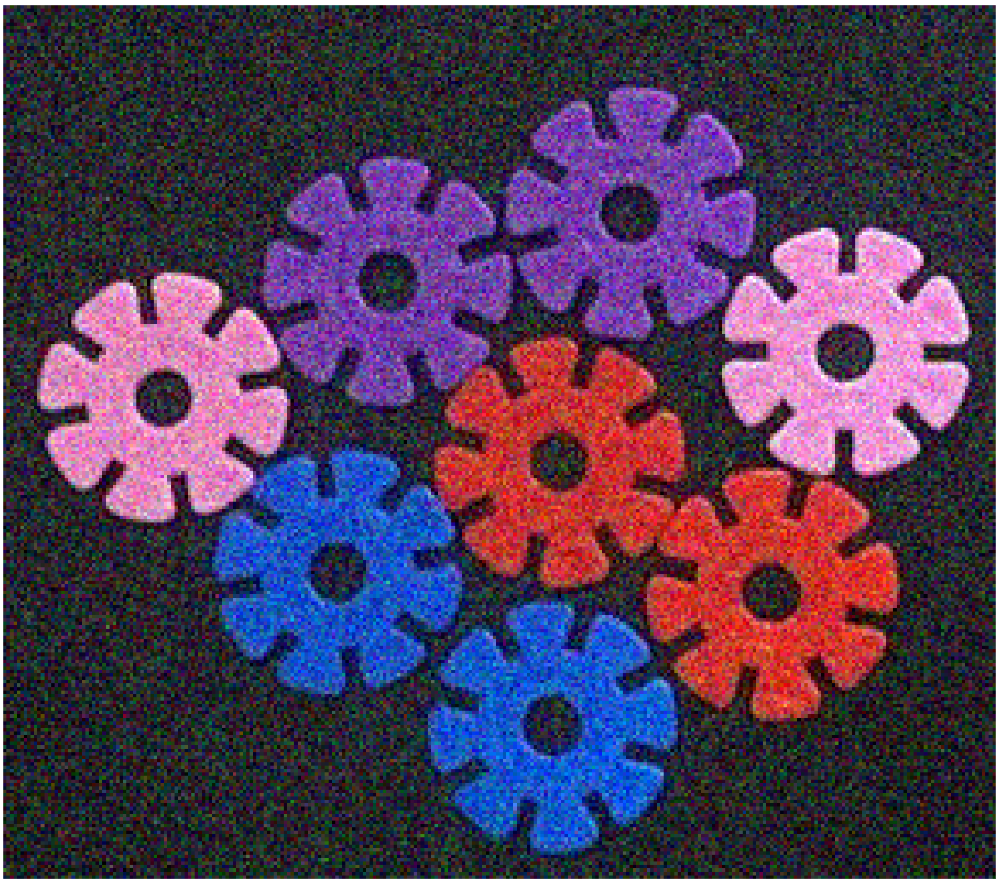

   **Try**. Use edge detection to find and count the number of circles representative of the number of gears. 

- *Adjust the slider to vary sigma to attain the correct number of gears in the image. *

    Step2 = imread("GearB.jpg");
    Step2 = imnoise(Step2, "gaussian");
    ImgGr = im2gray(Step2);
    ImgEdge = edge(ImgGr,"canny",0.2,0.9);  
    [centers,radii] = imfindcircles(ImgEdge,[8,20]);% Adjust the radius range as needed
    figure
    imshow(ImgEdge); % Display the original image
    hold on % Hold the current image
    viscircles(centers,radii,EdgeColor=[0.6350,0.0780,0.1840]); % Draw circles on the image
    hold off % Release the hold on the current image
    numCircles = length(radii); % Count the number of circles
    disp("Number of circles found: " + numCircles); % Display the count

### Step 3. Monitor stock levels to detect low stock and trigger restocking alerts.

   **Try**. Use **k-means clustering** to identify the number of blue gears in your inventory.

- *First, use k-means clustering to segment your image and adjust the number of k-clusters.*

- *Isolate the blue cluster by selecting the target cluster number from the spinner below.*

    Step3 = imread("GearC.jpg");
    k = 3;
    L = KImClust(Step3,k);

    % Choose a specific cluster to segment
    figure
    TargetCluster2 = 2; % Change this value for different clusters
    SegmentedImg2 = VizClust(Step3,L,TargetCluster2);
    montage({Step3,SegmentedImg2},Size=[1,2])
    ax = gca;
    ax.PositionConstraint = "outerposition";
    title("Original Image (Left) and Segmented Image (Right)")

  **Try**. Count the number of blue gears.

    radiusRange = [15,50]; 
    if exist("Step3","var") || exist("SegmentedImg2","var")
        % Detect circles in the binary image
        [centers, radii] = imfindcircles(SegmentedImg2,radiusRange,ObjectPolarity="dark",Sensitivity=0.92);

        figure
        montage({SegmentedImg2,labeloverlay(Step3,L)},Size=[1,2])
        title("Target Cluster Segmented Image (Left) and Detected Circles Image (Right)");
        hold on
        viscircles(centers,radii,EdgeColor=[0.6350,0.0780,0.1840]); % Overlay detected circles
        hold off

        numCircles = length(radii); % Count the number of circles
        disp("Number of circles found: "+numCircles); % Display the count
    else
        warning("Select a Valid Target Cluster or value of k in Step 3.")
    end

### Step 4. Ensure conveyor belts are operating efficiently.

  **Try**. Visualize the optical flow vectors for the two videos below. 

    ChosenVid = "Select"; % Select Video
    if ~strcmp(ChosenVid,"Select")
        FrameDepth = 30;
        SecondFrameFlow = OptFlow(ChosenVid,FrameDepth);
        SpeedCalc(SecondFrameFlow)
    else
        warning("Select a valid option.")
    end

 **Exercise 2. **Calculate the speed of the object in both videos. Which video has the fastest speed?

**Solution:**

    option = "Video of Gear 2";
    CheckAnswer("exercise2",option)

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

    function CheckAnswer(exerciseID,option)
    % Define the structure for each exercise (answers and hints)
    exercises = struct( ...
        "exercise1", struct("answer","Edge Detection","hint","Which method provides high level details?"),...
        "exercise2", struct("answer","Video of Gear 2","hint","Which speed is the greatest?")...
        );
    % Check if the exercise exists
    if isfield(exercises,exerciseID)
        CorrectAnswer = exercises.(exerciseID).answer;
        hint = exercises.(exerciseID).hint;

        % Compare answers
        if isequal(option,CorrectAnswer)
            disp("You are correct.");
        elseif isequal(option,"Select")
            warning("Select a valid option.")
        else
            warning("%s",hint);
        end
    else
        warning("Exercise not found.");
    end
    end


    function SecondFrameFlow = OptFlow(ChosenMovie,FrameDepth)
    vidReader = VideoReader(ChosenMovie, CurrentTime=1);
    FrameNum = vidReader.NumFrames;
    flowModel = opticalFlowLK;
    FirstFrame = read(vidReader,(FrameNum-FrameDepth));
    FirstFrameG = im2gray(FirstFrame);
    SecondFrame = read(vidReader,FrameNum);
    SecondFrameG = im2gray(SecondFrame);
    FirstFrameFlow = estimateFlow(flowModel,FirstFrameG); %#ok<*NASGU>
    SecondFrameFlow = estimateFlow(flowModel,SecondFrameG);

    % Define annotation positions
    position1 = [10,10]; % Top-left corner of the first frame

    % Define annotation text
    text1 = "First Frame + Optical Flow Vectors";
    text2 = "Second Frame";

    f = figure;
    f.Units = "pixels";
    screensize = get(0,"ScreenSize");
    f.Position = screensize;
    t = tiledlayout(1,2); % Create a tiled layout with 1 row and 2 columns
    nexttile
    imshow(FirstFrame)
    title(text1)

    % Add optical flow vectors to the first frame
    hold on
    plot(SecondFrameFlow,DecimationFactor=[10,10],ScaleFactor=5,Color=[0.3010,0.7450,0.9330]);
    hold off

    nexttile
    imshow(SecondFrame)
    title(text2)

    g=figure;
    imagesc(SecondFrameFlow.Magnitude)
    axis image; % Maintain aspect ratio
    gca.XTick = []; % Remove x-ticks
    gca.YTick = []; %#ok<*STRNU> % Remove y-ticks
    title("Motion Color Intensity Map")
    colorbar

    % Scale the imagesc image to the size of FirstFrame
    set(g,"Units","pixels")
    screensize = get(0,"ScreenSize");
    set(gcf,"Position",screensize)
    end


    function SpeedCalc(SecondFrameFlow)
    % Calculate the magnitude of the flow vectors
    magnitudeFlow = sqrt(SecondFrameFlow.Vx.^2+SecondFrameFlow.Vy.^2);

    % Define the time interval between frames (assuming 30 frames per second)
    TimeInterval = 1/30; % seconds

    % Calculate the speed (magnitude of flow vectors divided by time interval)
    speed = magnitudeFlow/TimeInterval;

    % Display the average speed
    AverageSpeed = mean(speed(:));
    disp("Average speed of the object: " + AverageSpeed + "pixels/second");
    end

    function L = KImClust(Img,k) % Function to perform K-means clustering on image
    [L,~] = imsegkmeans(Img,k);
    labeloverlay(Img,L);
    end

    function SegmentedImg = VizClust(ClustImg,L,TargetCluster)
    % Create a binary mask
    mask = L == TargetCluster;

    % Apply mask to the original image
    SegmentedImg = ClustImg;
    SegmentedImg(repmat(~mask,[1,1,3])) = 0;

    end